
Yaa =
 
    -50.02 s^7 - 4.553e04 s^6 - 5.316e06 s^5 + 4.71e06 s^4 + 8.161e09 s^3 + 2.134e11 s^2 + 2.103e12 s + 7.307e12
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 1351 s^7 + 5.111e05 s^6 + 8.109e07 s^5 + 5.938e09 s^4 + 1.988e11 s^3 + 3.294e12 s^2 + 2.648e13 s + 8.252e13
 
连续时间传递函数。


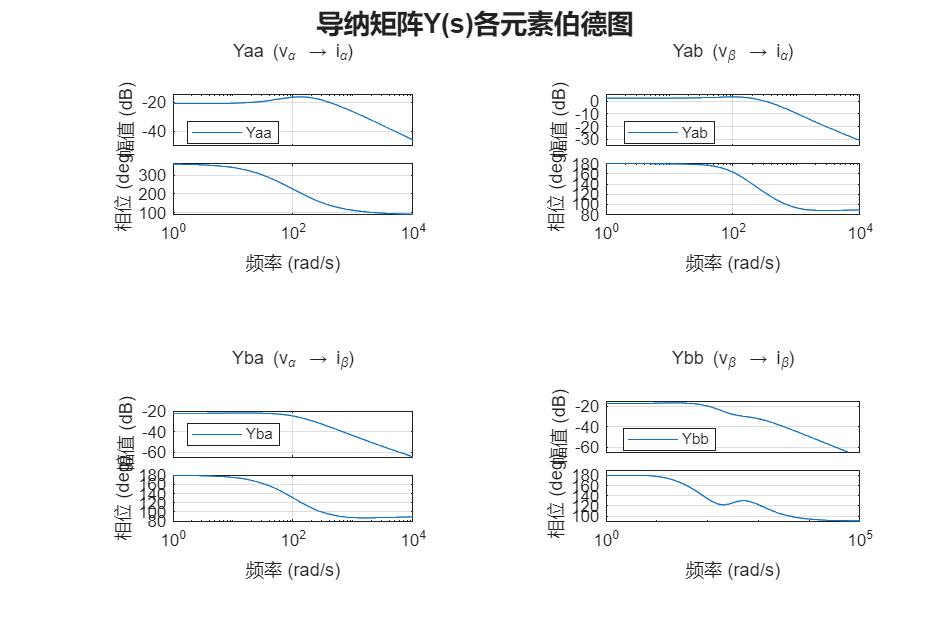


Zaa =
 
  1.399e-05 s^15 + 0.02764 s^14 + 21.42 s^13 + 9220 s^12 + 2.44e06 s^11 + 4.111e08 s^10 + 4.459e10 s^9 + 3.128e12 s^8 + 1.431e14 s^7 + 4.357e15 s^6 + 8.992e16 s^5 + 1.263e18 s^4 + 1.191e19 s^3 + 7.221e19 s^2 + 2.543e20 s + 3.959e20
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
                      s^13 + 1532 s^12 + 7.631e05 s^11 + 1.844e08 s^10 + 2.489e10 s^9 + 2e12 s^8 + 9.962e13 s^7 + 3.212e15 s^6 + 6.904e16 s^5 + 1.001e18 s^4 + 9.674e18 s^3 + 5.987e19 s^2 + 2.147e20 s + 3.395e20
 
连续时间传递函数。


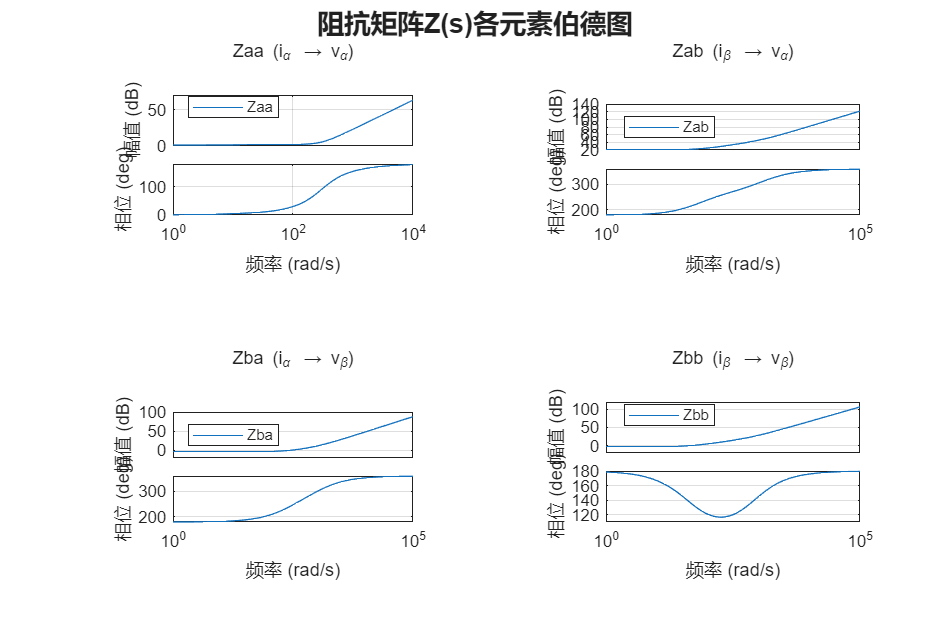

%% analyze_Y_grid.m
% 输入：Y (2x2 tf), 连续时间
% 可选输入：Zg_ab (2x2 tf)；若没有则用对称 RL 构造
% 输出：耦合指标、模态导纳、并网稳定性（eigenloci + det(I+L) + Ms）

clear; clc;
run("Admittancesingle.mlx")

%% ===== 0) 读取 / 检查 =====
assert(exist('Y','var')==1, '工作区需要变量 Y（2x2 tf 矩阵）');
assert(isa(Y,'tf') && all(size(Y)==[2 2]), 'Y 必须是 2x2 tf');
assert(Y(1,1).Ts==0, '脚本针对连续系统 Ts=0');

s = tf('s');

% 转状态空间用于极点检查（MIMO 极点看 ss 更靠谱）
Yss = ss(Y);
pY  = pole(Yss);
fprintf('Y 极点数（含重数）：%d\n', numel(pY));

Y 极点数（含重数）：16


fprintf('Y 是否稳定：%d （1=稳定，0=不稳定）\n', all(real(pY)<0));

Y 是否稳定：1 （1=稳定，0=不稳定）


disp('Y 极点：'); disp(pY.');

Y 极点：
 -854.8603 -211.3749 -125.8270 -103.0862  -17.0302  -14.8570  -13.6251  -10.2132 -854.8603 -211.3749 -125.8270 -103.0862  -17.0302  -14.8570  -13.6251  -10.2132



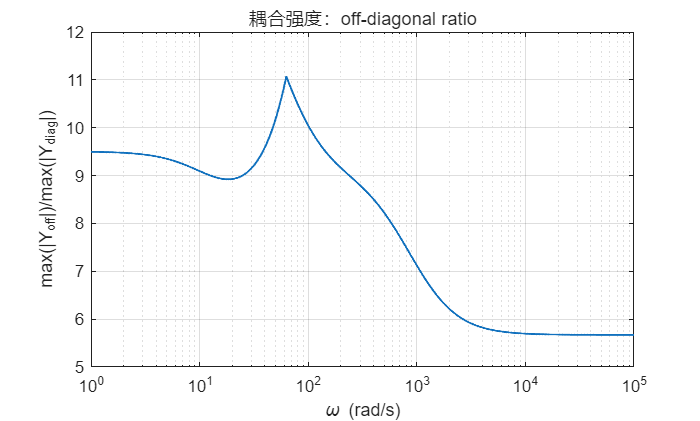


%% ===== 1) 电网阻抗 Zg_ab =====
% 情况A：你已经有 Zg_ab（2x2 tf）就直接用
if exist('Zg_ab','var')==1
    assert(isa(Zg_ab,'tf') && all(size(Zg_ab)==[2 2]), 'Zg_ab 必须是 2x2 tf');
else
    % 情况B：没有就用最常见对称 RL 网格模型：Zg = (Rg + Lg*s) * I
    Rg = 0.2;        % 欧姆（示例，按你的系统改）
    Lg = 1e-3;       % 亨（示例，按你的系统改）
    Zg_ab = (Rg + Lg*s) * eye(2);
end

%% ===== 2) 频率网格 =====
w = logspace(0, 5, 2000);   % 1 ~ 1e5 rad/s（按需要改）
jw_resp_Y = freqresp(Y, w);     % 2x2xN
jw_resp_Zg = freqresp(Zg_ab, w);  % 2x2xN

N = numel(w);

%% ===== 3) 耦合强弱指标 =====
% 3.1 off-diagonal ratio：|Y12|,|Y21| 相对对角线的比例
off_ratio = zeros(1,N);
condY     = zeros(1,N);
rga12     = zeros(1,N);
rga21     = zeros(1,N);

for k = 1:N
    Yk = jw_resp_Y(:,:,k);

    % off-diagonal 相对对角线（一个粗但直观的耦合强度）
    diag_mag = max([abs(Yk(1,1)), abs(Yk(2,2)), 1e-12]);
    off_mag  = max([abs(Yk(1,2)), abs(Yk(2,1))]);
    off_ratio(k) = off_mag / diag_mag;

    % 条件数：越大越"难解耦/敏感"
    condY(k) = cond(Yk);

    % 频率相关 RGA：RGA = Y .* (inv(Y)).'  （.' 是不共轭转置）
    % 注意：若 Yk 接近奇异，RGA 会发散，这是信息（说明该频点耦合/病态）
    if rcond(Yk) > 1e-10
        RGAk = Yk .* (inv(Yk)).';
        rga12(k) = abs(RGAk(1,2));
        rga21(k) = abs(RGAk(2,1));
    else
        rga12(k) = NaN;
        rga21(k) = NaN;
    end
end

%% ===== 4) 模态（特征值）导纳：把 2x2 导纳"看成两个模态通道" =====
lamY = zeros(2,N);
Vref = [];                  % 用于固定一个参考方向，减少"特征向量跳变"
T0   = [];                  % 选定某个频点的解耦变换

% 选择一个"代表性频点"来固定解耦变换（通常选工频附近 or 控制带宽附近）
w0 = 2*pi*50; % 50Hz 示例；若你是60Hz改成 2*pi*60
[~,k0] = min(abs(w - w0));

for k = 1:N
    Yk = jw_resp_Y(:,:,k);
    [Vk,Dk] = eig(Yk);              % Yk*Vk = Vk*Dk
    lam = diag(Dk);

    % 为了让曲线更连续：按特征值幅值排序
    [~,idx] = sort(abs(lam),'descend');
    lam = lam(idx);
    Vk  = Vk(:,idx);

    lamY(:,k) = lam;

    if k == k0
        T0 = Vk; % 在 w0 处选取模态变换
    end
end

% 用 T0 做"近似解耦"（固定变换）：Y_modal ≈ inv(T0)*Y*T0
Y_modal = zeros(2,2,N);
for k = 1:N
    Yk = jw_resp_Y(:,:,k);
    Y_modal(:,:,k) = (T0\Yk)*T0;
end

%% ===== 5) 并网稳定性（MIMO 阻抗法）：L = Zg * Y =====
lamL = zeros(2,N);       % L(jw) 的特征值轨迹（eigenloci）
Ms   = zeros(1,N);       % sensitivity 最大奇异值（鲁棒性指标）

for k = 1:N
    Yk  = jw_resp_Y(:,:,k);
    Zgk = jw_resp_Zg(:,:,k);

    Lk = Zgk * Yk;

    % eigenloci（看是否靠近/绕过 -1）
    lam = eig(Lk);
    [~,idx] = sort(abs(lam),'descend');
    lamL(:,k) = lam(idx);

    % 灵敏度矩阵 S = inv(I + L)
    I2 = eye(2);
    M = (I2 + Lk);

    if rcond(M) > 1e-12
        Sk = inv(M);
        Ms(k) = max(svd(Sk));   % 峰值越大，鲁棒性越差
    else
        Ms(k) = Inf;
    end
end

%% ===== 6) 可视化 =====
figure; semilogx(w, off_ratio, 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('max(|Y_{off}|)/max(|Y_{diag}|)');
title('耦合强度：off-diagonal ratio');

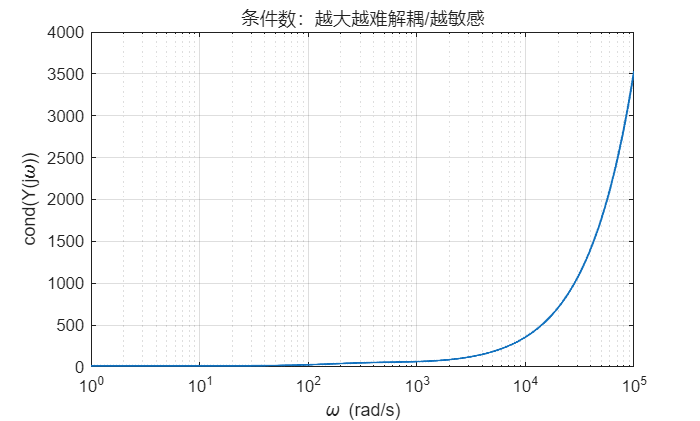


figure; semilogx(w, condY, 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('cond(Y(j\omega))');
title('条件数：越大越难解耦/越敏感');

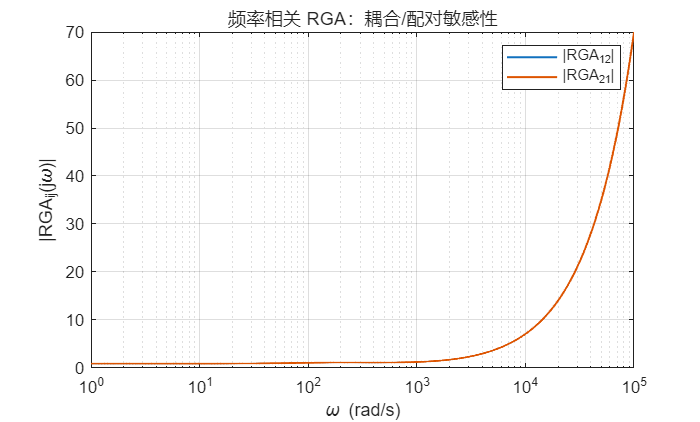


figure; semilogx(w, rga12, 'LineWidth', 1.2); hold on;
semilogx(w, rga21, 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('|RGA_{ij}(j\omega)|');
legend('|RGA_{12}|','|RGA_{21}|');
title('频率相关 RGA：耦合/配对敏感性');

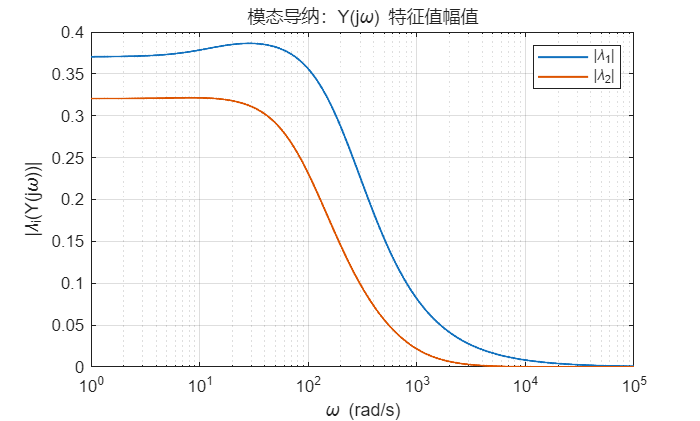


% 模态导纳特征值幅值
figure; semilogx(w, abs(lamY(1,:)), 'LineWidth', 1.2); hold on;
semilogx(w, abs(lamY(2,:)), 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('|\lambda_i(Y(j\omega))|');
legend('|\lambda_1|','|\lambda_2|');
title('模态导纳：Y(j\omega) 特征值幅值');

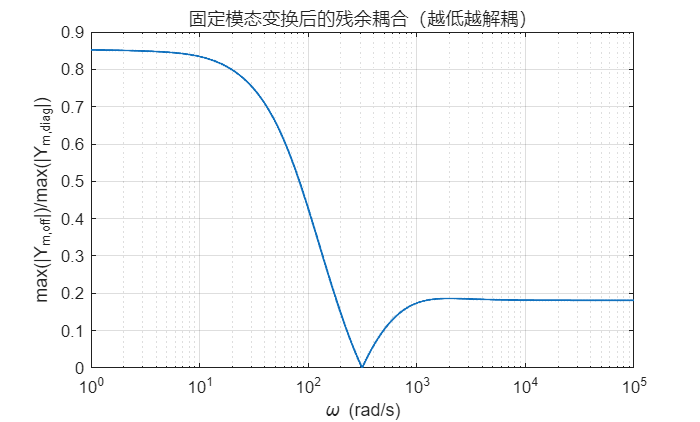


% 固定变换后的"近似对角化"程度：看 Y_modal 的非对角项
ym_off = zeros(1,N);
ym_diag = zeros(1,N);
for k=1:N
    Ym = Y_modal(:,:,k);
    ym_off(k)  = max([abs(Ym(1,2)), abs(Ym(2,1))]);
    ym_diag(k) = max([abs(Ym(1,1)), abs(Ym(2,2)), 1e-12]);
end
figure; semilogx(w, ym_off./ym_diag, 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('max(|Y_{m,off}|)/max(|Y_{m,diag}|)');
title('固定模态变换后的残余耦合（越低越解耦）');

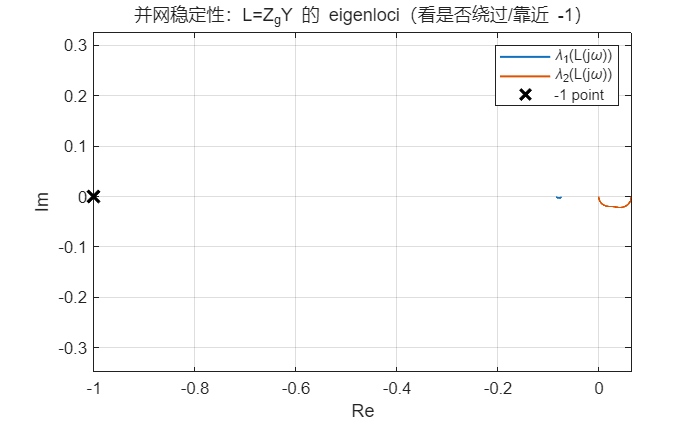


% 并网稳定性：L 的特征值轨迹（eigenloci）在复平面
figure;
plot(real(lamL(1,:)), imag(lamL(1,:)), 'LineWidth', 1.2); hold on;
plot(real(lamL(2,:)), imag(lamL(2,:)), 'LineWidth', 1.2);
plot(-1,0,'kx','MarkerSize',10,'LineWidth',2);
grid on; axis equal;
xlabel('Re'); ylabel('Im');
legend('\lambda_1(L(j\omega))','\lambda_2(L(j\omega))','-1 point');
title('并网稳定性：L=Z_gY 的 eigenloci（看是否绕过/靠近 -1）');

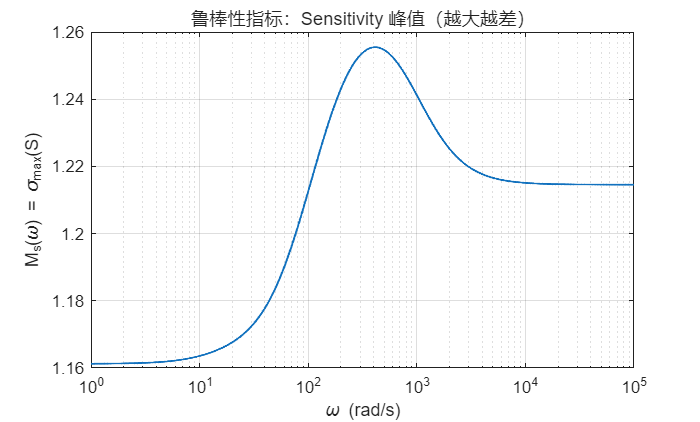


% 鲁棒性：Ms = max singular value of S = (I+L)^{-1}
figure; semilogx(w, Ms, 'LineWidth', 1.2);
grid on; xlabel('\omega (rad/s)'); ylabel('M_s(\omega) = \sigma_{max}(S)');
title('鲁棒性指标：Sensitivity 峰值（越大越差）');


%% ===== 7) 给出关键数值摘要 =====
[Ms_peak, idx_peak] = max(Ms);
fprintf('\n=== 摘要 ===\n');


=== 摘要 ===


fprintf('最大 off_ratio = %.3g （发生在 ω=%.3g rad/s）\n', max(off_ratio), w(off_ratio==max(off_ratio)));

最大 off_ratio = 11.1 （发生在 ω=62.9 rad/s）


fprintf('最大 cond(Y)   = %.3g （发生在 ω=%.3g rad/s）\n', max(condY), w(condY==max(condY)));

最大 cond(Y)   = 3.53e+03 （发生在 ω=1e+05 rad/s）


fprintf('Ms 峰值        = %.3g （发生在 ω=%.3g rad/s）\n', Ms_peak, w(idx_peak));

Ms 峰值        = 1.26 （发生在 ω=413 rad/s）


fprintf('提示：eigenloci 若包围或逼近 -1，通常意味着并网不稳/低裕度。\n');

提示：eigenloci 若包围或逼近 -1，通常意味着并网不稳/低裕度。
